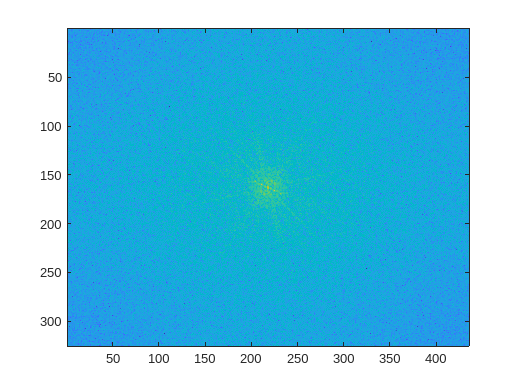

clc;clear;

I = im2double(im2gray(imread("Train/captcha_0654.png")));

fourier = fftshift(fft2(I));
fourier2 = fftshift(fft2(I));
imagesc(log(abs(fourier)))

absFourier = abs(fourier);
maxValue = max(absFourier(:));
thresh_val = 0.01 * maxValue;
mask = absFourier < thresh_val;
fourierFilt = fourier .* mask;
fourier(160,211) = 0;
fourier(157,204) = 0;
fourier(166,225) = 0;
fourier(169,232) = 0;
filteredImage = ifft2(ifftshift(fourier)) + mean2(I);
filteredImage = mat2gray(real(filteredImage));
% crop = filteredImage(1:100, 1:100); imshow(crop); cropHist = imhist(crop);
% J = imgaussfilt(filteredImage,4);
% imshow(J);
X1 = EM_DenoiseTV(filteredImage,0.2);


Iterations:    0, E: 4970.7472 -> 4970.7472                              
Iterations:    1, E: 4970.7472 -> 3364.1522                              
Iterations:    2, E: 4970.7472 -> 3120.1329                              
Iterations:    3, E: 4970.7472 -> 2041.7001                              
Iterations:    4, E: 4970.7472 -> 1867.0165                              
Iterations:    5, E: 4970.7472 -> 1665.4836                              
Iterations:    6, E: 4970.7472 -> 1551.2718                              
Iterations:    7, E: 4970.7472 -> 1493.9655                              
Iterations:    8, E: 4970.7472 -> 1457.2753                              
Iterations:    9, E: 4970.7472 -> 1432.9412                              
Iterations:   10, E: 4970.7472 -> 1416.6750                              
Iterations:   11, E: 4970.7472 -> 1405.1859                              
Iterations:   12, E: 4970.7472 -> 1396.6929                              
Iterations:   13, E: 4970.7472 -> 139

X2 =  histeq(X1);
absJ = abs(X1);
maxValueJ = max(absJ(:));
binaryImage = X2 < 0.09;
original = binaryImage

original = 325×435 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

disk = strel("disk",2);
line = strel("line",2,180);
line2 = strel("line",5,90);
% for i = 1:2
%     binaryImage = imerode(binaryImage,SE);
% end
binaryImage = original;
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,line);
binaryImage = imdilate(binaryImage,disk);
binaryImage = imerode(binaryImage,line2)

binaryImage = 325×435 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

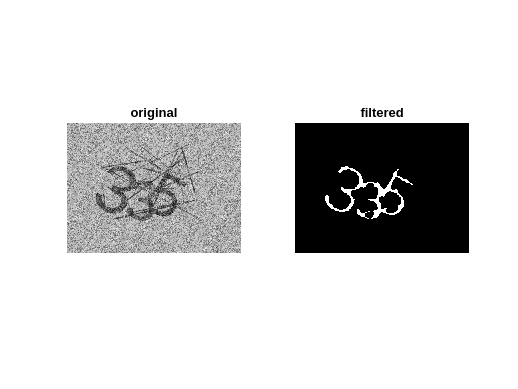



figure;
subplot(1, 2, 1);
imshow(filteredImage);
title('original');

subplot(1, 2, 2);
imshow(binaryImage);
title('filtered');

%Read in the 5
test2 = rgb2gray(imread("5.jpg"))

test2 = 130×87 uint8 matrix
     0     1     0     0     0     0     0     2     1     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     1     0     0     1     0     3     0     1     5     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     1     0     0     0     0     5     0     0     4     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     1     0     0     1     6     0     0   

%Rotate it
test2 = imrotate(test2,-30)

test2 = 157×141 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

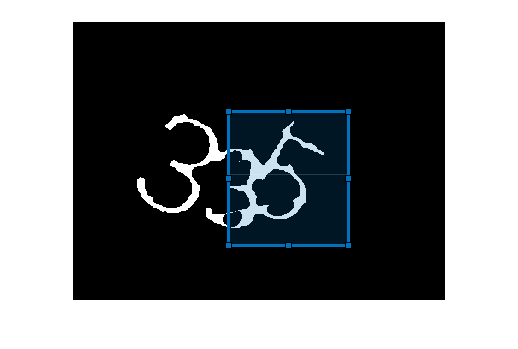

% %Call cross correlation matching in fourier domain
% [y,x]=templatematch(binaryImage*255,test2)
% 
% %Draw the template
% template  = test2;
% background = binaryImage*255;
% %crop background
% bx = size(background, 2); 
% by = size(background, 1);
% tx = size(template, 2);
% ty = size(template, 1);

%% display best match
hFig = figure;
hAx  = axes;
position = [x, y, tx, ty];
imshow(background);
drawrectangle('Position',position);

templates=[test2]

templates = 157×141 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

rotations=[0,10,20,30,-10,-20,-30]

rotations =      0    10    20    30   -10   -20   -30


%for template in templates:
%    for rotation in rotation:
correlations = templatematch(background,template)

correlations =     0.0010    0.0009    0.0031   -0.0012    0.0003    0.0019   -0.0017    0.0010    0.0007   -0.0016   -0.0022   -0.0027   -0.0018   -0.0018    0.0014   -0.0007    0.0002   -0.0027   -0.0019    0.0048   -0.0041    0.0026    0.0020    0.0035   -0.0016    0.0003   -0.0016    0.0026    0.0041    0.0020   -0.0032   -0.0012    0.0013   -0.0001    0.0009    0.0019   -0.0032   -0.0032   -0.0014    0.0066    0.0063    0.0004   -0.0009   -0.0032    0.0005   -0.0001   -0.0025   -0.0010    0.0036    0.0025
    0.0024    0.0006    0.0012    0.0003    0.0020    0.0002   -0.0016    0.0004   -0.0011    0.0003    0.0021    0.0001    0.0015    0.0008   -0.0012   -0.0003   -0.0021   -0.0006    0.0030    0.0023   -0.0021    0.0034    0.0012    0.0012   -0.0019   -0.0011   -0.0008    0.0025    0.0018   -0.0005   -0.0007   -0.0023    0.0022    0.0007   -0.0016   -0.0005   -0.0024   -0.0006    0.0068    0.0053   -0.0020   -0.0036   -0.0034   -0.0046    0.0007    0.0023    0.0001    0.0021    

splits=split_vector(correlations,10)

splits = 33×44 cell array
    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {0×0 double}
    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}    {10×10 double}   

[across,down] = size(splits)

across = 33

down = 44

max_values = zeros((down-1),(across-1))

max_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    

for i = 1:across-1
    for j =1:down-1
        max_values(i,j)=max(splits{i,j},[],'all');
    end
end
topKRows = maxk(max_values, 3, 1);  % Top k elements along each column
top_3 = maxk(topKRows, 1, 2);  % Top k elements along each row

% Iterate over 3,4,5 for different scales and rotations
    % Compute top 3 region of matches (To catch 333,444,555 etc)
% Take top 3 matches out of all matches and thats the prediction